#### ROSCO gains calculator and linearisation

load turbine data and steady state points:

load("SS_IEA15MW.mat");
load("bladedata_IEA_15MW.mat");

linearisation of the aerodynamic loads near the steady state points:

indexSS=[1:length(SS.WINDSPEED)];
L=length(indexSS);
V0=SS.WINDSPEED;
omega=SS.ROTSPD;
theta=SS.BLADEPITCH;

cv=zeros(L,1);
cw=zeros(L,1);
ct=zeros(L,1);
kv=zeros(L,1);
kw=zeros(L,1);
kt=zeros(L,1);
pitchSensitivity=zeros(L,1);

for v=1:L
[THRUST1,TANG1,BENDING1,TORQUE1,POWER1]=BEM(V0(v)-1,omega(v),theta(v),bladedata);
[THRUST2,TANG2,BENDING2,TORQUE2,POWER2]=BEM(V0(v)+1,omega(v),theta(v),bladedata);

cv(v)=(THRUST2-THRUST1)*3/2; % [N/(m/s)]
kv(v)=(TORQUE2-TORQUE1)*3/2; % [Nm/(m/s)]

[THRUST1,TANG1,BENDING1,TORQUE1,POWER1]=BEM(V0(v),omega(v)-1,theta(v),bladedata);
[THRUST2,TANG2,BENDING2,TORQUE2,POWER2]=BEM(V0(v),omega(v)+1,theta(v),bladedata);

cw(v)=(THRUST2-THRUST1)*3/2; % [N/RPM]
kw(v)=(TORQUE2-TORQUE1)*3/2; % [Nm/RPM]

[THRUST1,TANG1,BENDING1,TORQUE1,POWER1]=BEM(V0(v),omega(v),theta(v)-(1),bladedata);
[THRUST2,TANG2,BENDING2,TORQUE2,POWER2]=BEM(V0(v),omega(v),theta(v)+(1),bladedata);

ct(v)=(THRUST2-THRUST1)*3/(2); % [N/deg]
kt(v)=(TORQUE2-TORQUE1)*3/(2); % [Nm/deg]
pitchSensitivity(v)=(POWER2-POWER1)/(2); % [MW/deg]

end

compute pitch sensitivity for gain scheduled $\frac{\textrm{dP}}{d\theta \;}$ through an approximation of a second order polynomial

i=find(SS.POWER>=SS.POWER(end)*0.95);
p=polyfit([0 SS.BLADEPITCH(i)],[pitchSensitivity(i(1));pitchSensitivity(i)],2);
theta=[0:25];
pitchSensitivity_approx=p(1)*theta.^2+p(2)*theta+p(3);

plot 

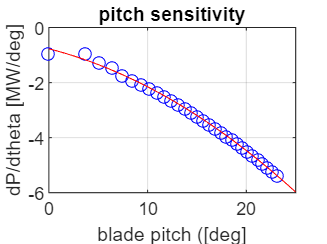

plot([0 SS.BLADEPITCH(i)],[pitchSensitivity(i(1));pitchSensitivity(i)],'ob')
hold on
plot(theta,pitchSensitivity_approx,'r')
grid on
title("pitch sensitivity")
xlabel("blade pitch ([deg]")
ylabel("dP/dtheta [MW/deg]")
xlim([0 25])
hold off

salva i dati sulla linearizzazione

linear.cv=cv;
linear.cw=cw;
linear.ct=ct;
linear.kv=kv;
linear.kw=kw;
linear.kt=kt;
linear.pitchSensitivity=pitchSensitivity;
linear.theta=theta;
linear.pitchSensitivity_approx=pitchSensitivity_approx;
save("linear_IEA15MW","linear");